# 3D Quadcopter Modelling and Simulation

% parameters
m = 0.65; % kg
l = 0.23; % m
b = 3.13 * 10^-5; % Ns^2
d = 7.5 * 10^-7; % Ns^2
I_x = 7.5 * 10^-3; % kgm^2
I_y = 7.5 * 10^-3; % kgm^2
I_z = 1.3 * 10^-2;  % kgm^2
J_R = 6.5 * 10^-5; % kgm^2
w_max = 1000; % rad/sec
t_max = 0.15; % Nm
g = 9.81; % m/s^2

% inputs 
U_1 = m*g;
U_2 = 0;
U_3 = 0;
U_4 = 0; 

% state space for motor speed
A = [1/(4*b) 0 1/(2*b*l) 1/(4*d);
    1/(4*b) -1/(2*b*l) 0 1/(4*d);
    -1/(4*b) 0 -1/(2*b*l) -1/(4*d);
    1/(4*b) 1/(2*b*l) 0 1/(4*d)];

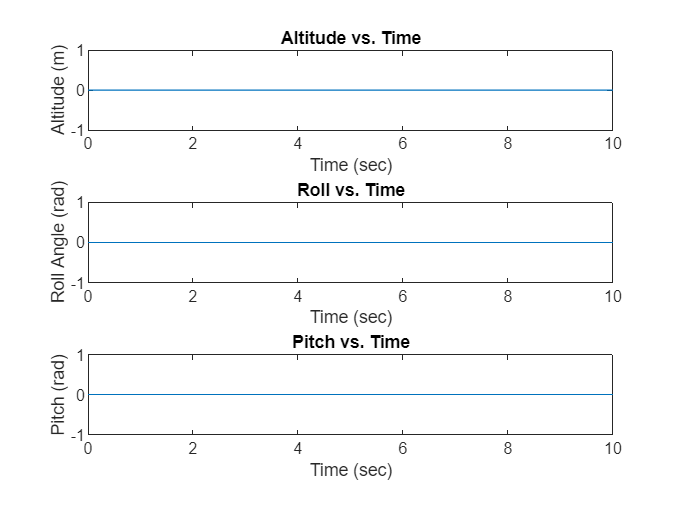

t0 = 0; % start time
dt = 0.001; % step time
tf = 10; % final time

% Define time vector 
t = t0:dt:tf;

% Length of time array so we know the number of integration steps to make
N = length(t);

% Create placeholder arrays of zeros for the solution and the first derivative
x = zeros(1,N);
x_dot = zeros(1,N);
y = zeros(1,N);
y_dot = zeros(1,N);
z = zeros(1,N);
z_dot = zeros(1,N);
phi = zeros(1,N);
phi_dot = zeros(1,N);
theta = zeros(1,N);
theta_dot = zeros(1,N);
psi = zeros(1,N);
psi_dot = zeros(1,N);

% Set initial conditions
x(1) = 0;
x_dot(1) = 0;
y(1) = 0;
y_dot(1) = 0;
z(1) = 0;
z_dot(1) = 0;
phi(1) = 0;
phi_dot(1) = 0;
theta(1) = 0;
theta_dot(1) = 0;
psi(1) = 0;
psi_dot(1) = 0;

% PID controller gains
Kp1 = 1.8; Ki1 = 0; Kd1 = 2;
Kp2 = 0.4; Ki2 = 0; Kd2 = 0.2;
Kp3 = 0.6; Ki3 = 0; Kd3 = 0.2;
Kp4 = 0.3; Ki4 = 0; Kd4 = 0.2;

% initial desired states
z_des = zeros(N, 1);
phi_des = zeros(N, 1);
theta_des = zeros(N, 1);
psi_des = zeros(N, 1);

% initialize error vectors and constants
z_error = zeros(N, 1);
I_1 = 0;
phi_error = zeros(N, 1);
I_2 = 0;
theta_error = zeros(N, 1);
I_3 = 0;
psi_error = zeros(N, 1);
I_4 = 0;

% loop through time steps using euler integration
for i = 1:N-1    
    % step input at 1 sec
    if i == 1/dt
        z_des(i:end, 1) = 1;
        phi_des(i:end, 1) = 0;
        theta_des(i:end, 1) = 0;
        psi_des(i:end, 1) = 1;
    end

    % PID controller for alititude (U_1)
    z_error(i) = z_des(i) - z(i);
    P_1 = Kp1 * z_error(i);
    I_1 = I_1 + Ki1 * z_error(i) * dt;
    D_1 = 0;
    if i > 1
        D_1 = (Kd1 * (z(i) - z(i-1)) / dt);
    end
    U_1 = (m/(cos(phi(i))*cos(theta(i))))*(g+P_1+I_1-D_1);

    % PID controller for roll (U_2)
    phi_error(i) = phi_des(i) - phi(i);
    P_2 = Kp2 * phi_error(i);
    I_2 = I_2 + Ki2 * phi_error(i) * dt;
    D_2 = 0;
    if i > 1
        D_2 = (Kd2 * (phi(i) - phi(i-1)) / dt);
    end
    U_2 = P_2+I_2-D_2;

    % PID controller for pitch (U_3)
    theta_error(i) = theta_des(i) - theta(i);
    P_3 = Kp3 * theta_error(i);
    I_3 = I_3 + Ki3 * theta_error(i) * dt;
    D_3 = 0;
    if i > 1
        D_3 = (Kd3 * (theta(i) - theta(i-1)) / dt);
    end
    U_3 = P_3+I_3-D_3;

    % PID controller for yaw (U_4)
    psi_error(i) = psi_des(i) - psi(i);
    P_4 = Kp4 * psi_error(i);
    I_4 = I_4 + Ki4 * psi_error(i) * dt;
    D_4 = 0;
    if i > 1
        D_4 = (Kd4 * (psi(i) - psi(i-1)) / dt);
    end
    U_4 = P_4+I_4-D_4;

    W = A * [U_1; U_2; U_3; U_4]; % compute motor speeds
    w_r = -W(1) + W(2) - W(3) + W(4);

    x_ddot = (sin(theta(i))*cos(phi(i))*cos(psi(i)) + sin(psi(i))*sin(phi(i))) * (U_1/m);
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
    
    y_ddot = (sin(psi(i))*sin(theta(i))*cos(phi(i)) - cos(psi(i))*sin(phi(i))) * (U_1/m);
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    z_ddot = (cos(phi(i))*cos(theta(i)))*(U_1/m) - g;
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;

    phi_ddot = ((I_y-I_z)/I_x)*theta_dot(i)*psi_dot(i) + (J_R/I_x)*theta_dot(i)*w_r + (l/I_x)*U_2;
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;

    theta_ddot = ((I_z-I_x)/I_y)*theta_dot(i)*psi_dot(i) + (J_R/I_x)*phi_dot(i)*w_r + (l/I_y)*U_3;
    theta_dot(i+1) = theta_dot(i) + theta_ddot*dt;
    theta(i+1) = theta(i) + theta_dot(i)*dt;

    psi_ddot = ((I_x-I_y)/I_z)*phi_dot(i)*theta_dot(i) + U_4/I_z;
    psi_dot(i+1) = psi_dot(i) + psi_ddot*dt;
    psi(i+1) = psi(i) + psi_dot(i)*dt;
end

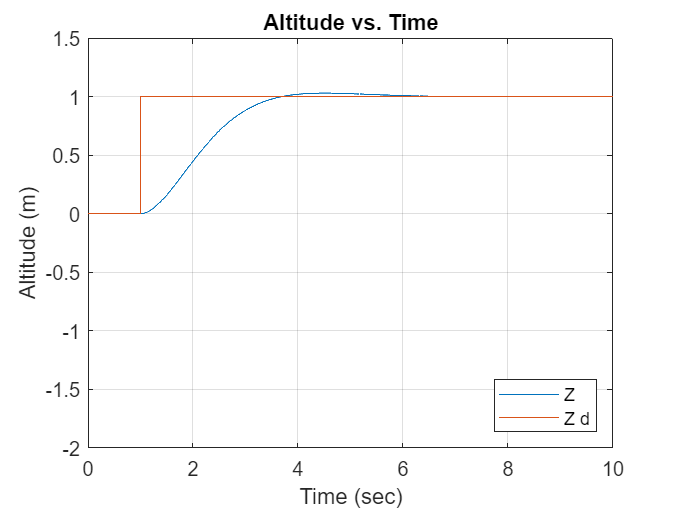

% plot data
figure;
plot(t, z)
hold on
plot(t, z_des)
hold off
grid
axis([0 10 -2 1.5])
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")
legend("Z", "Z d", "Location", "southeast")

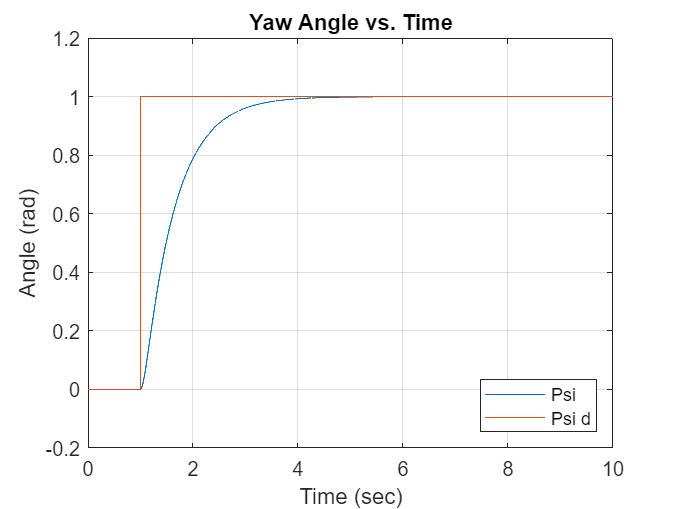


plot(t, psi)
hold on
plot(t, psi_des)
hold off
grid
axis([0 10 -0.2 1.2])
title("Yaw Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")
legend("Psi", "Psi d", "Location", "southeast")

% PID controller gains
Kp1 = 6.35; Ki1 = 0; Kd1 = 0;
Kp2 = 110; Ki2 = 50; Kd2 = 3;
Kp3 = 16; Ki3 = 10; Kd3 = 10;
Kp4 = 8; Ki4 = 10; Kd4 = 2;

% initial desired states
z_des = zeros(N, 1);
phi_des = zeros(N, 1);
theta_des = zeros(N, 1);
psi_des = zeros(N, 1);

% initialize error vectors and constants
z_error = zeros(N, 1);
I_1 = 0;
phi_error = zeros(N, 1);
I_2 = 0;
theta_error = zeros(N, 1);
I_3 = 0;
psi_error = zeros(N, 1);
I_4 = 0;

% initialize motor torques
U_1 = zeros(N, 1);
U_2 = zeros(N, 1);
U_3 = zeros(N, 1);
U_4 = zeros(N, 1);

% loop through time steps using euler integration
for i = 1:N-1    
    % step input at 1 sec
    if i == 1/dt
        z_des(i:end, 1) = 1;
        phi_des(i:end, 1) = 0;
        theta_des(i:end, 1) = 0;
        psi_des(i:end, 1) = 1;
    end

    % PID controller for alititude (U_1)
    z_error(i) = z_des(i) - z(i);
    P_1 = Kp1 * z_error(i);
    I_1 = I_1 + Ki1 * z_error(i) * dt;
    D_1 = 0;
    if i > 1
        D_1 = (Kd1 * (z(i) - z(i-1)) / dt);
    end
    U_1(i, 1) = P_1+I_1-D_1;

    % PID controller for roll (U_2)
    phi_error(i) = phi_des(i) - phi(i);
    P_2 = Kp2 * phi_error(i);
    I_2 = I_2 + Ki2 * phi_error(i) * dt;
    D_2 = 0;
    if i > 1
        D_2 = (Kd2 * (phi(i) - phi(i-1)) / dt);
    end
    U_2(i, 1) = P_2+I_2-D_2;

    % PID controller for pitch (U_3)
    theta_error(i) = theta_des(i) - theta(i);
    P_3 = Kp3 * theta_error(i);
    I_3 = I_3 + Ki3 * theta_error(i) * dt;
    D_3 = 0;
    if i > 1
        D_3 = (Kd3 * (theta(i) - theta(i-1)) / dt);
    end
    U_3(i, 1) = P_3+I_3-D_3;

    % PID controller for yaw (U_4)
    psi_error(i) = psi_des(i) - psi(i);
    P_4 = Kp4 * psi_error(i);
    I_4 = I_4 + Ki4 * psi_error(i) * dt;
    D_4 = 0;
    if i > 1
        D_4 = (Kd4 * (psi(i) - psi(i-1)) / dt);
    end
    U_4(i, 1) = P_4+I_4-D_4;

    W = A * [U_1(i, 1); U_2(i, 1); U_3(i, 1); U_4(i, 1)]; % compute motor speeds
    w_r = -W(1) + W(2) - W(3) + W(4);

    x_ddot = (sin(theta(i))*cos(phi(i))*cos(psi(i)) + sin(psi(i))*sin(phi(i))) * (U_1(i, 1)/m);
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
    
    y_ddot = (sin(psi(i))*sin(theta(i))*cos(phi(i)) - cos(psi(i))*sin(phi(i))) * (U_1(i, 1)/m);
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    z_ddot = (cos(phi(i))*cos(theta(i)))*(U_1(i, 1)/m) - g;
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;

    phi_ddot = ((I_y-I_z)/I_x)*theta_dot(i)*psi_dot(i) + (J_R/I_x)*theta_dot(i)*w_r + (l/I_x)*U_2(i, 1);
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;

    theta_ddot = ((I_z-I_x)/I_y)*theta_dot(i)*psi_dot(i) + (J_R/I_x)*phi_dot(i)*w_r + (l/I_y)*U_3(i, 1);
    theta_dot(i+1) = theta_dot(i) + theta_ddot*dt;
    theta(i+1) = theta(i) + theta_dot(i)*dt;

    psi_ddot = ((I_x-I_y)/I_z)*phi_dot(i)*theta_dot(i) + U_4(i, 1)/I_z;
    psi_dot(i+1) = psi_dot(i) + psi_ddot*dt;
    psi(i+1) = psi(i) + psi_dot(i)*dt;
end

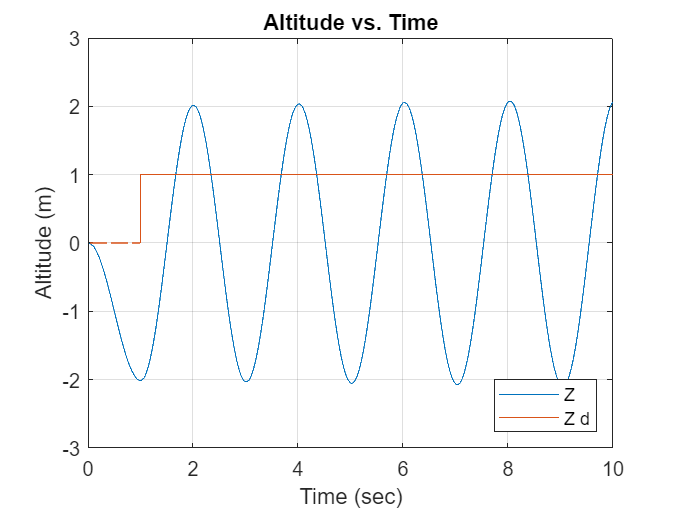

% plot data
figure;
plot(t, z)
hold on
plot(t, z_des)
hold off
grid
%axis([0 10 -2 1.5])
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")
legend("Z", "Z d", "Location", "southeast")

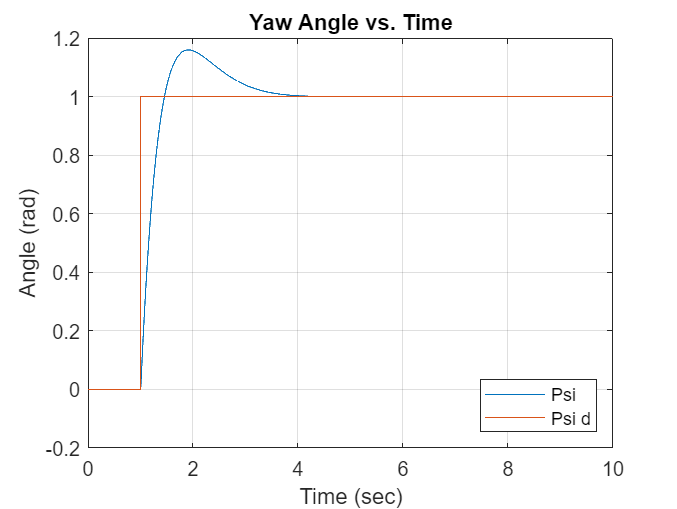


plot(t, psi)
hold on
plot(t, psi_des)
hold off
grid
axis([0 10 -0.2 1.2])
title("Yaw Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")
legend("Psi", "Psi d", "Location", "southeast")

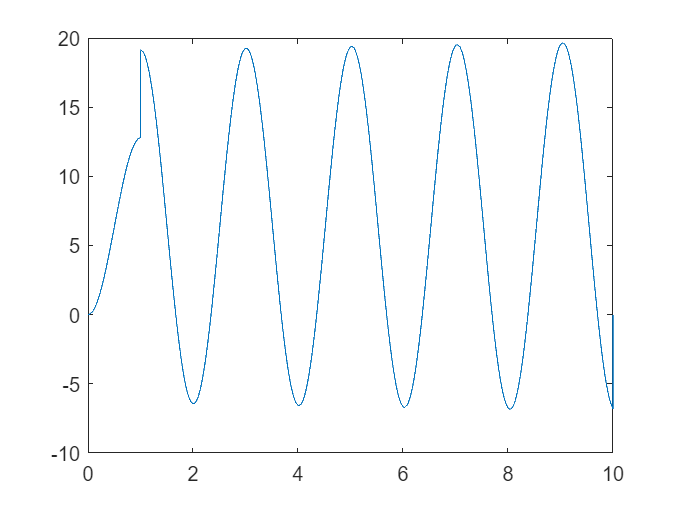

plot(t, U_1)